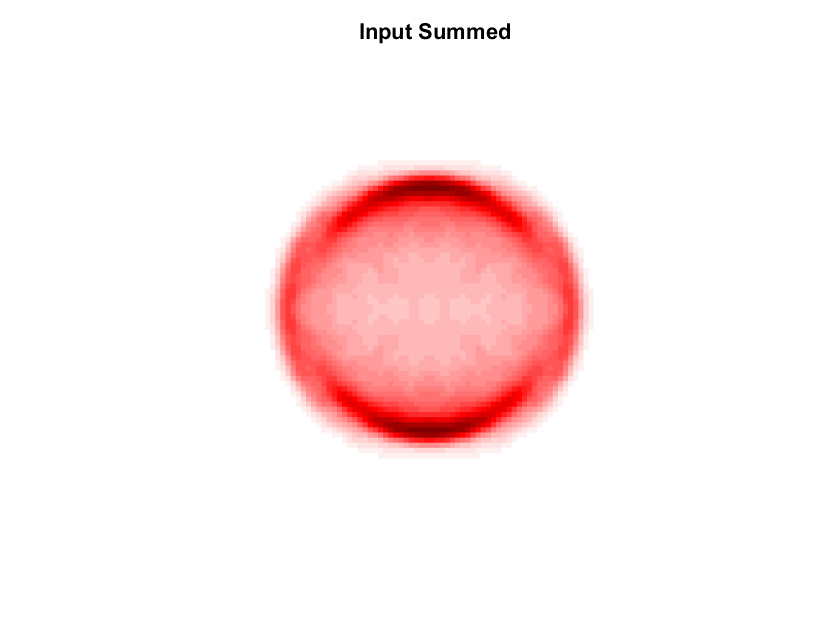

% This script was used to assess network output after a specific dataset
% was processed through a trained network. In this case, the specific
% dataset was created using the "process_through_network_lowcount" script.

% MPhys Research Project 2022/23
% Ross Anderson (H00295702)



% clear commands
clc
clear
close all

% set the run number, this is indicated by the gdrive file
run_no = 17;

% load all aspects of that run
load("G:\My Drive\MPhys Project\centroid\run_"+run_no+"\results_process.mat");
% load("G:\My Drive\MPhys Project\run_"+run_no+"\history.mat");
images_sampled_mat = load("G:\My Drive\MPhys Project\centroid\run_"+run_no+"\centroid_process.mat");
images_gaussfilt_mat = load("G:\My Drive\MPhys Project\centroid\run_"+run_no+"\gaussfilt_process.mat");
% images_mat = load("G:\My Drive\MPhys Project\centroid\run_"+run_no+"\images.mat");
coeffs = load("G:\My Drive\MPhys Project\centroid\run_"+run_no+"\coeffs_process.mat");
% coeffs = coeffs.coeffs;

images_sampled_mat = images_sampled_mat.images_sampled_mat;
images_gaussfilt_mat = images_gaussfilt_mat.images_gaussfilt_mat;

% convert the network_output in the correct dimensionality
network_output = results.predictions;
network_output = permute(network_output, [2, 3, 1]);

gaussfilt_summed = zeros(96, 96);
sampled_summed = zeros(96, 96);
output_summed = zeros(96, 96);


if run_no == 16
    % 10^3 counts
    N_max = 10^2;

elseif run_no == 17
    % 10^1 counts
    N_max = 10^4;

end


for N = 1:N_max

    gaussfilt_tot = flipcat_4fold(images_gaussfilt_mat(:,:,N));
    %         showim(gaussfilt_tot, 1)
    %         title("Network input")
    %         shading flat

    sampled_tot = flipcat_4fold(images_sampled_mat(:,:,N));
    %         showim(sampled_tot, 1)
    %         title("Truth")
    %         shading flat

    network_output_tot = flipcat_4fold(network_output(:, :, N));
    %         showim(network_output_tot, 1)
    %         title("Network output")
    %         shading flat

    gaussfilt_summed = imadd(gaussfilt_summed, gaussfilt_tot);
    sampled_summed = imadd(sampled_summed, sampled_tot);
    output_summed = imadd(output_summed, double(network_output_tot));

end

gaussfilt_summed = rescale(gaussfilt_summed);
sampled_summed = rescale(sampled_summed);
output_summed = rescale(output_summed);

showim(gaussfilt_summed, 1)
title("Input Summed")
shading flat

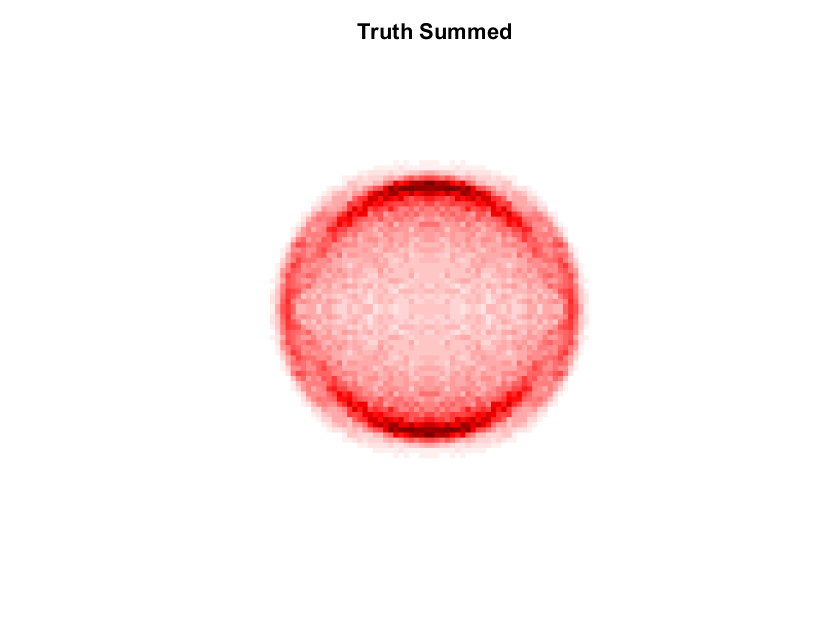


showim(sampled_summed, 1)
title("Truth Summed")
shading flat

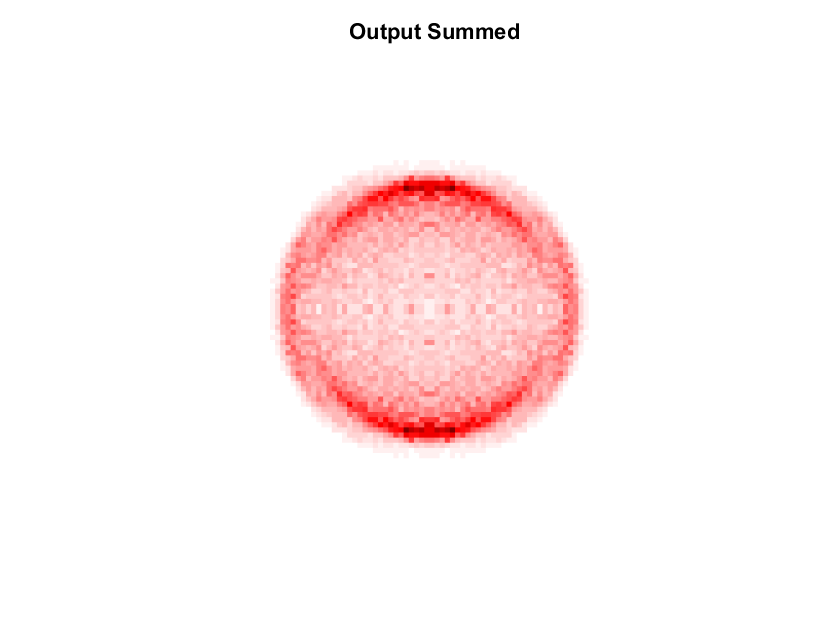


showim(output_summed, 1)
title("Output Summed")
shading flat

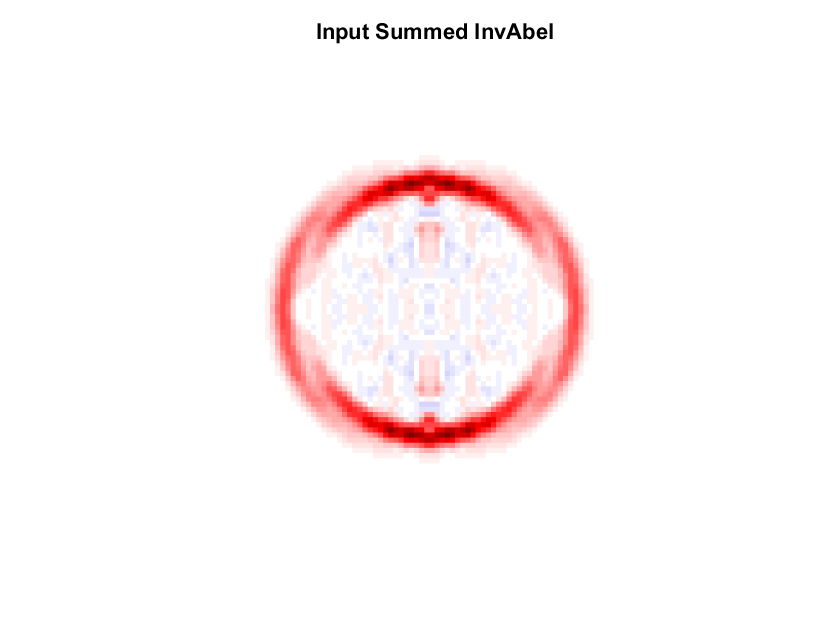



showim(InvAbel(gaussfilt_summed), 1)
title("Input Summed InvAbel")
shading flat

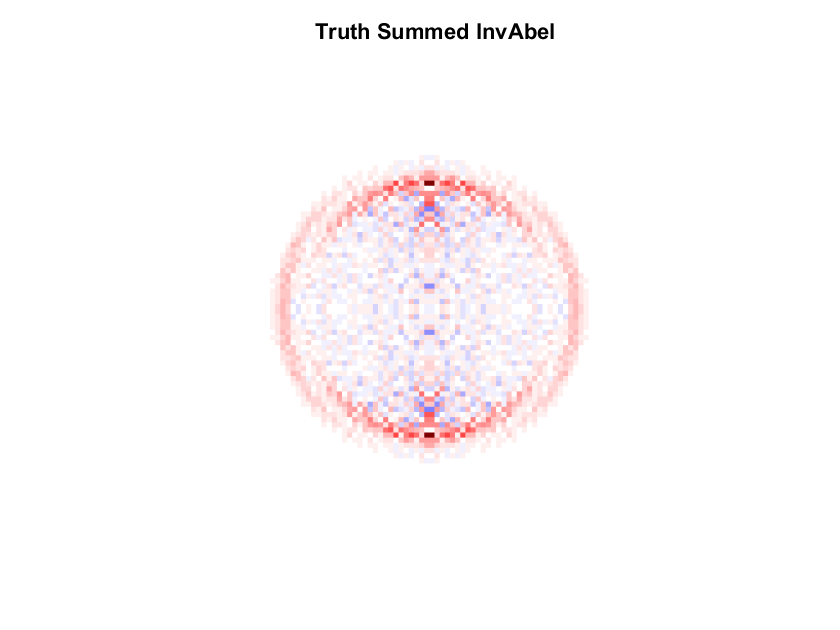


showim(InvAbel(sampled_summed), 1)
title("Truth Summed InvAbel")
shading flat

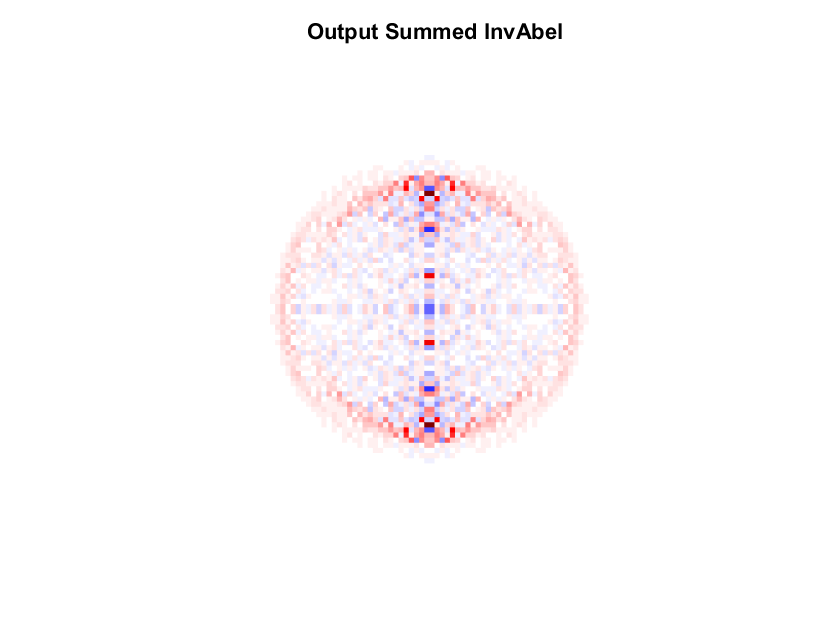


showim(InvAbel(output_summed), 1)
title("Output Summed InvAbel")
shading flat

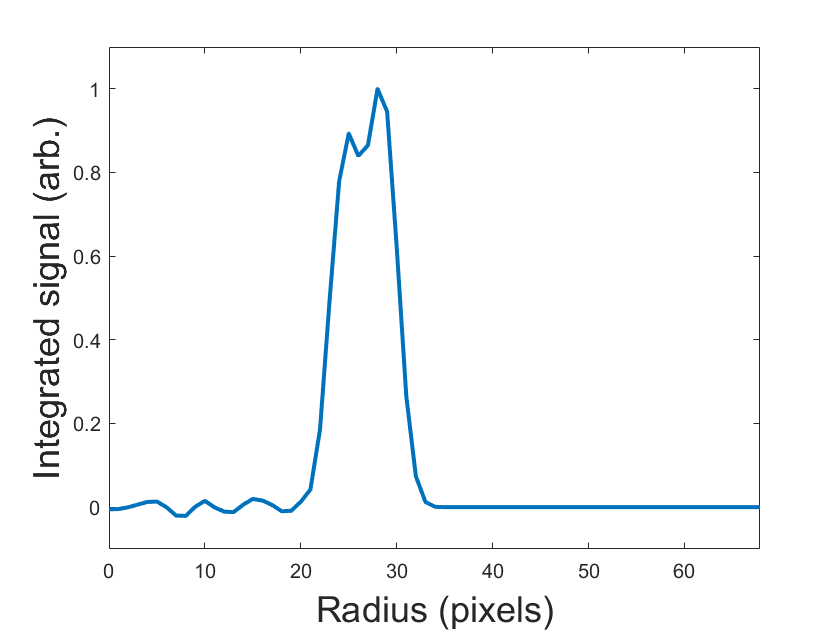



% rmse = sqrt(mean((sampled_summed(:)-output_summed(:)).^2));

[v_input, r] = velocity_dist(gaussfilt_summed, 96);
plot(r, v_input, "LineWidth", 2)
xlim([0, max(r)])
ylim([-0.1, 1.1])
xlabel("Radius (pixels)", "FontSize", 18)
ylabel("Integrated signal (arb.)", "FontSize", 18)

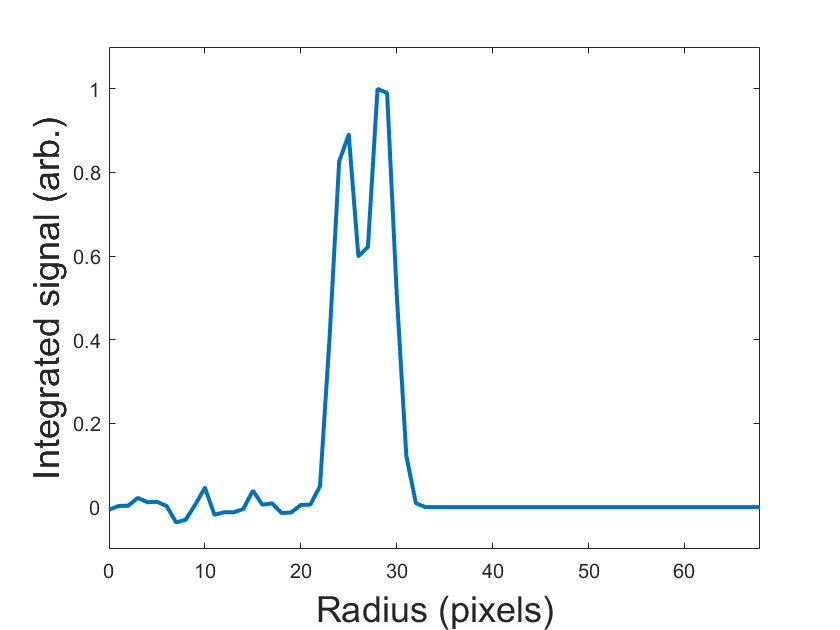

% title("Input")

[v_truth, r] = velocity_dist(sampled_summed, 96);
plot(r, v_truth, "LineWidth", 2)
xlim([0, max(r)])
ylim([-0.1, 1.1])
xlabel("Radius (pixels)", "FontSize", 18)
ylabel("Integrated signal (arb.)", "FontSize", 18)

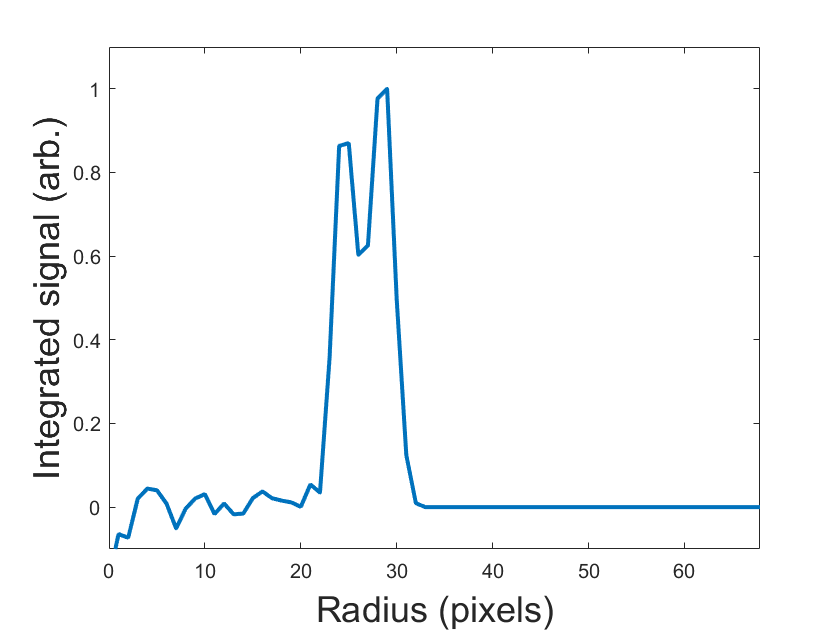

% title("Truth")

[v_output, r] = velocity_dist(output_summed, 96);
plot(r, v_output, "LineWidth", 2)
xlim([0, max(r)])
ylim([-0.1, 1.1])
xlabel("Radius (pixels)", "FontSize", 18)
ylabel("Integrated signal (arb.)", "FontSize", 18)

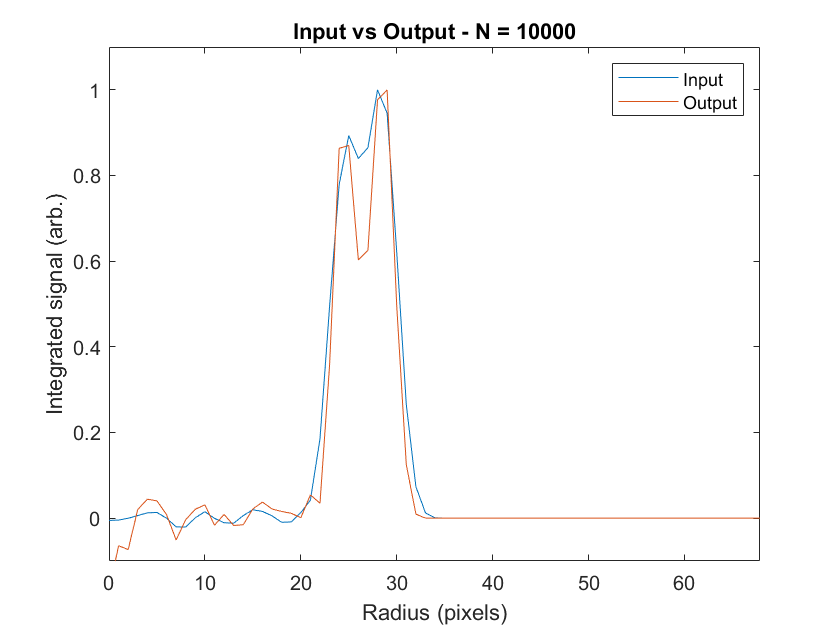

% title("Output")


plot(r, v_input)
hold on
plot(r, v_output)
hold off
xlim([0, max(r)])
ylim([-0.1, 1.1])
xlabel("Radius (pixels)")
ylabel("Integrated signal (arb.)")
title("Input vs Output - N = " + N)
legend("Input", "Output")

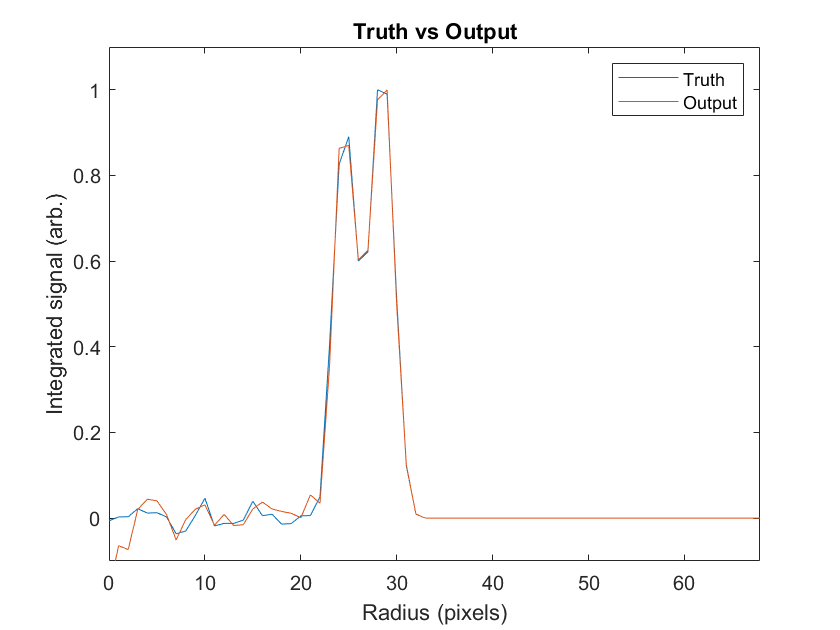



plot(r, v_truth)
hold on
plot(r, v_output)
hold off
xlim([0, max(r)])
ylim([-0.1, 1.1])
xlabel("Radius (pixels)")
ylabel("Integrated signal (arb.)")
title("Truth vs Output")
legend("Truth", "Output")

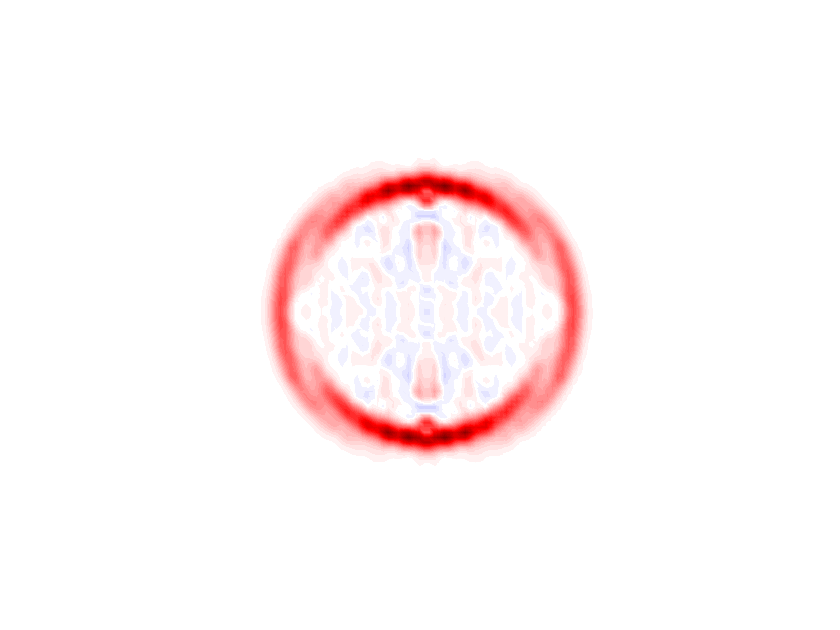





% beta2
input_inverted = InvAbel(gaussfilt_summed);
showim(input_inverted, 1)

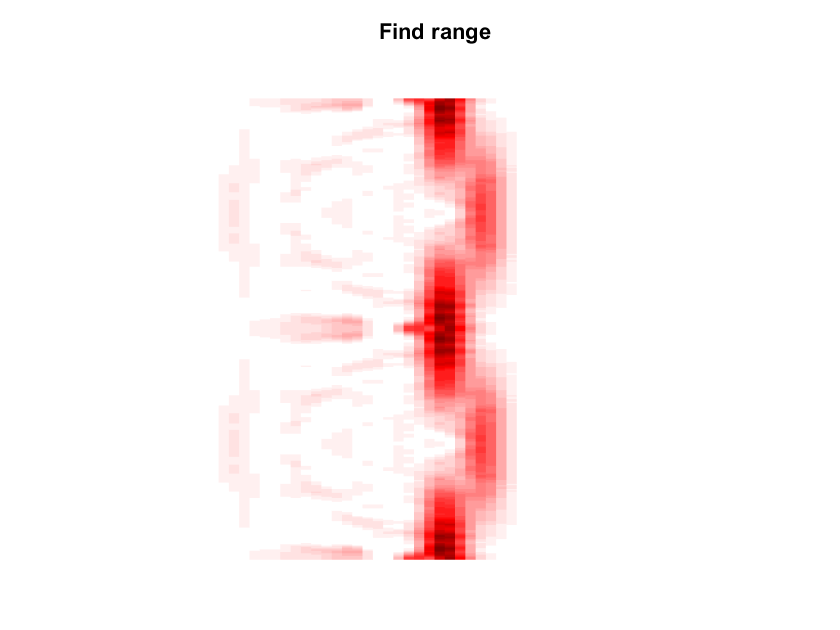


I_pol_original = cart_2_polar(input_inverted', [48,360]);
I_pol_original(I_pol_original<0) = 0;
showim(I_pol_original, 1)
title("Find range")
shading flat

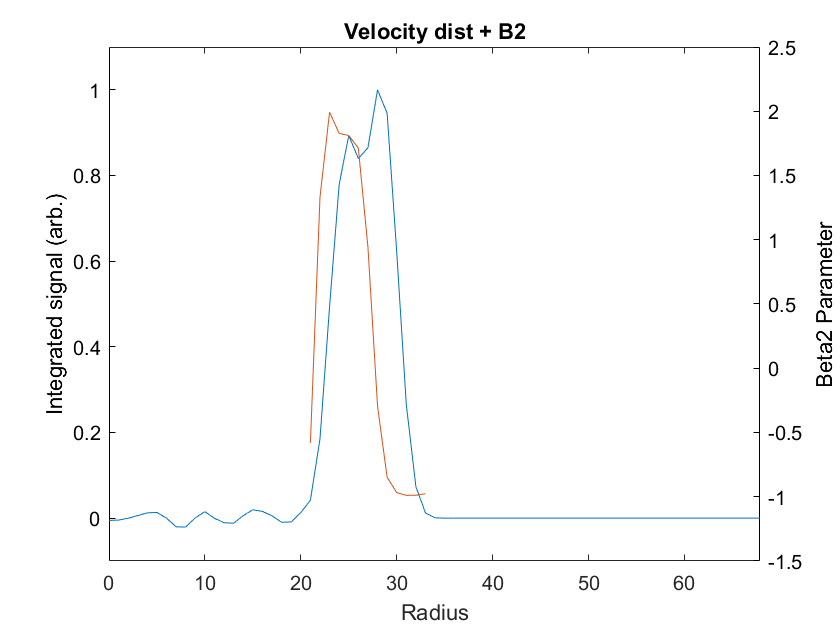


if run_no == 16

    range_min = 23;
    range_max = 33;

elseif run_no == 17

    range_min = 21;
    range_max = 33;

end



beta2_input = find_beta2_customres(input_inverted, 96, range_min, range_max);

figure()
yyaxis left
plot(r, v_input)
xlim([0, max(r)])
ylim([-0.1, 1.1])
xlabel("Radius (pixels)")
ylabel("Integrated signal (arb.)")

yyaxis right
plot(range_min:range_max, beta2_input)
title("Velocity dist + B2")
xlabel("Radius")
ylabel("Beta2 Parameter")
xlim([0, max(r)])
ylim([-1.5, 2.5])

ax = gca;
ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'k';

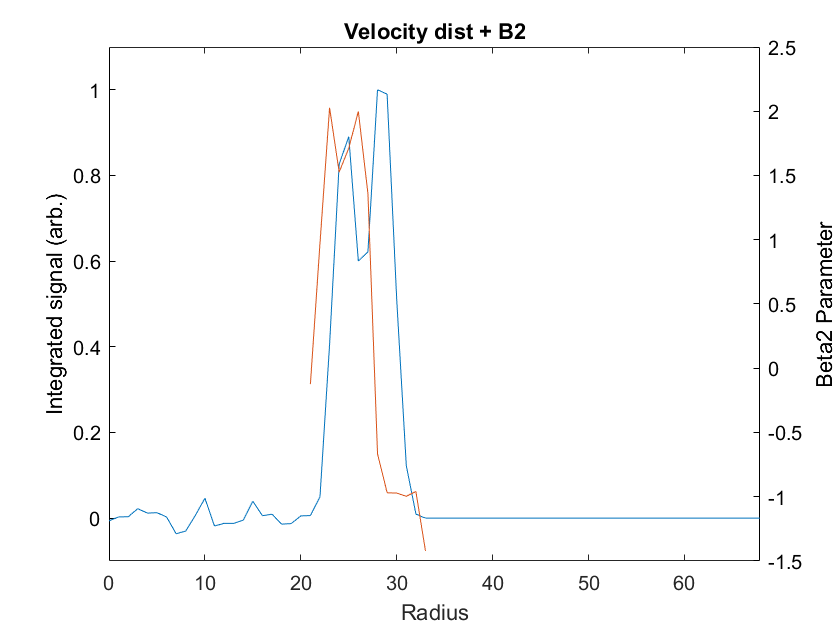





% beta2
truth_inverted = InvAbel(sampled_summed);

% I_pol_original = cart_2_polar(truth_inverted', [48,360]);
% I_pol_original(I_pol_original<0) = 0;
% showim(I_pol_original, 1)
% title("Find range")
% shading flat

% range_min = 18;
% range_max = 28;

beta2_truth = find_beta2_customres(truth_inverted, 96, range_min, range_max);

figure()
yyaxis left
plot(r, v_truth)
xlim([0, max(r)])
ylim([-0.1, 1.1])
xlabel("Radius (pixels)")
ylabel("Integrated signal (arb.)")

yyaxis right
plot(range_min:range_max, beta2_truth)
title("Velocity dist + B2")
xlabel("Radius")
ylabel("Beta2 Parameter")
xlim([0, max(r)])
ylim([-1.5, 2.5])

ax = gca;
ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'k';

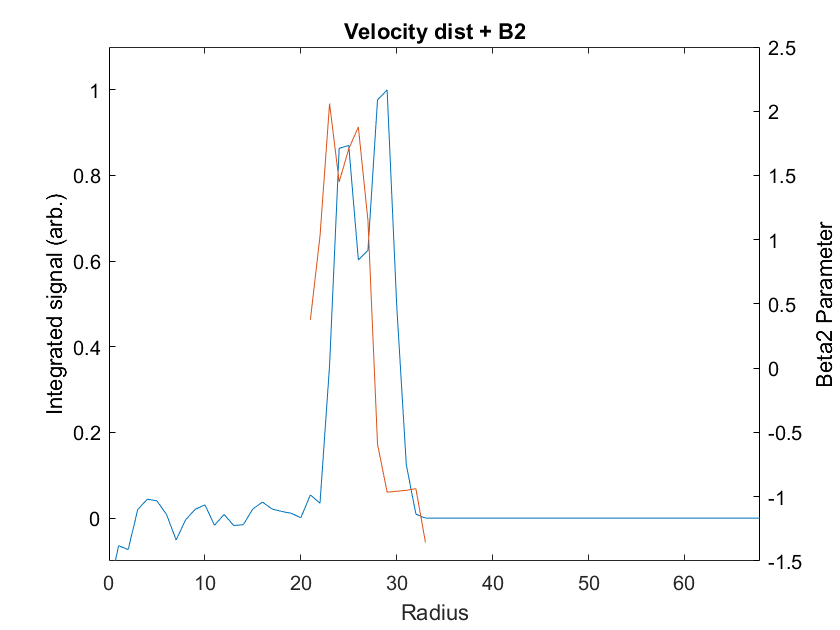





% beta2
output_inverted = InvAbel(output_summed);

% showim(I_pol_original, 1)
% title("Find range")
% shading flat

% range_min = 16;
% range_max = 26;

beta2_output = find_beta2_customres(output_inverted, 96, range_min, range_max);

figure()
yyaxis left
plot(r, v_output)
xlim([0, max(r)])
ylim([-0.1, 1.1])
xlabel("Radius (pixels)")
ylabel("Integrated signal (arb.)")

yyaxis right
plot(range_min:range_max, beta2_output)
title("Velocity dist + B2")
xlabel("Radius")
ylabel("Beta2 Parameter")
xlim([0, max(r)])
ylim([-1.5, 2.5])

ax = gca;
ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'k';

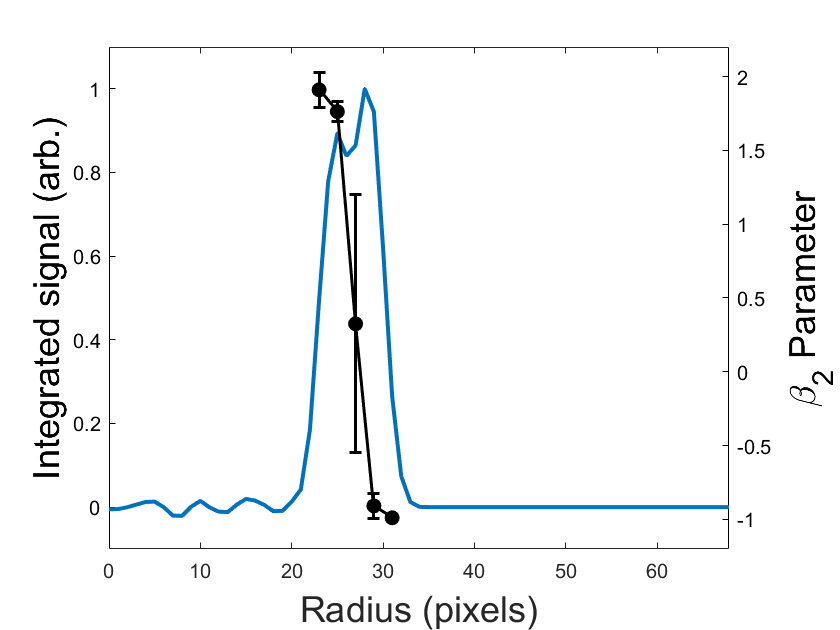



bin_size = 2;

[binned_beta2_input, error_input] = bin_beta2(beta2_input, bin_size);

[binned_beta2_truth, error_truth] = bin_beta2(beta2_truth, bin_size);

[binned_beta2_output, error_output] = bin_beta2(beta2_output, bin_size);

radius_points = range_min:bin_size:range_max;



figure()
% plot on top of velocity distributions!
yyaxis left
plot(r, v_input, "LineWidth", 2)
% title("Velocity distribution - Network output (with B2)")
xlim([0, max(r)])
ylim([-0.1, 1.1])
xlabel("Radius (pixels)", "FontSize", 18)
ylabel("Integrated signal (arb.)", "FontSize", 18)

yyaxis right
e = errorbar(radius_points(2:length(binned_beta2_input)), binned_beta2_input(2:end), error_input(2:end));
ylim([-1.2, 2.2])
ylabel("\beta_2 Parameter", "FontSize", 18)
% legend("Velocity Distribution", "\beta_2 Parameter")
e.Marker = 'o';
e.MarkerEdgeColor = 'black';
e.MarkerFaceColor = 'black';
e.Color = 'black';
e.LineWidth = 1.5;

ax = gca;
ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'k';

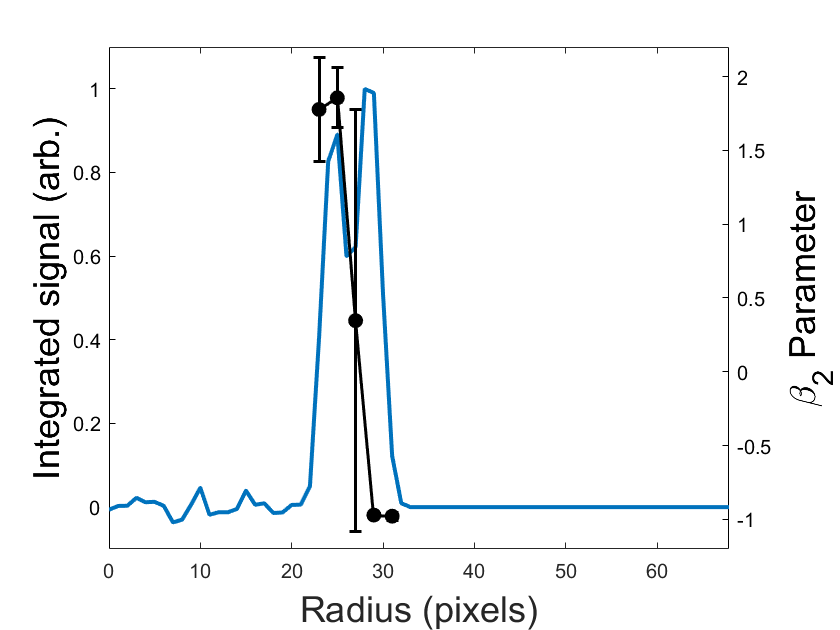




figure()
% plot on top of velocity distributions!
yyaxis left
plot(r, v_truth, "LineWidth", 2)
% title("Velocity distribution - Network output (with B2)")
xlim([0, max(r)])
ylim([-0.1, 1.1])
xlabel("Radius (pixels)", "FontSize", 18)
ylabel("Integrated signal (arb.)", "FontSize", 18)

yyaxis right
e = errorbar(radius_points(2:length(binned_beta2_truth)), binned_beta2_truth(2:end), error_truth(2:end));
ylim([-1.2, 2.2])
ylabel("\beta_2 Parameter", "FontSize", 18)
% legend("Velocity Distribution", "\beta_2 Parameter")
e.Marker = 'o';
e.MarkerEdgeColor = 'black';
e.MarkerFaceColor = 'black';
e.Color = 'black';
e.LineWidth = 1.5;

ax = gca;
ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'k';

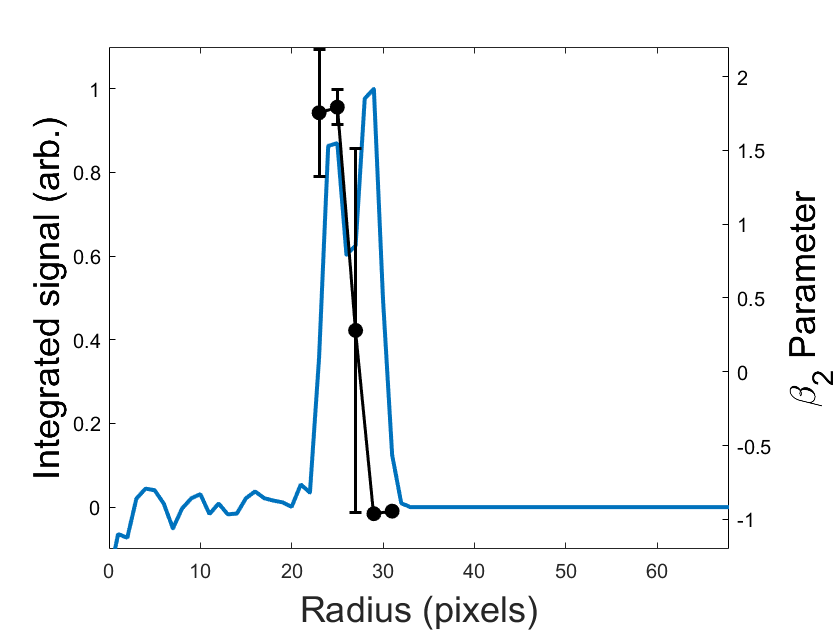




figure()
% plot on top of velocity distributions!
yyaxis left
plot(r, v_output, "LineWidth", 2)
% title("Velocity distribution - Network output (with B2)")
xlim([0, max(r)])
ylim([-0.1, 1.1])
xlabel("Radius (pixels)", "FontSize", 18)
ylabel("Integrated signal (arb.)", "FontSize", 18)

yyaxis right
e = errorbar(radius_points(2:length(binned_beta2_output)), binned_beta2_output(2:end), error_output(2:end));
ylim([-1.2, 2.2])
ylabel("\beta_2 Parameter", "FontSize", 18)
% legend("Velocity Distribution", "\beta_2 Parameter")
e.Marker = 'o';
e.MarkerEdgeColor = 'black';
e.MarkerFaceColor = 'black';
e.Color = 'black';
e.LineWidth = 1.5;

ax = gca;
ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'k';



%for perfect b2 for 10^1 counts, start at 2:end
